# Binomial model for bernoulli trials

## Binom(n,p) with n = 40

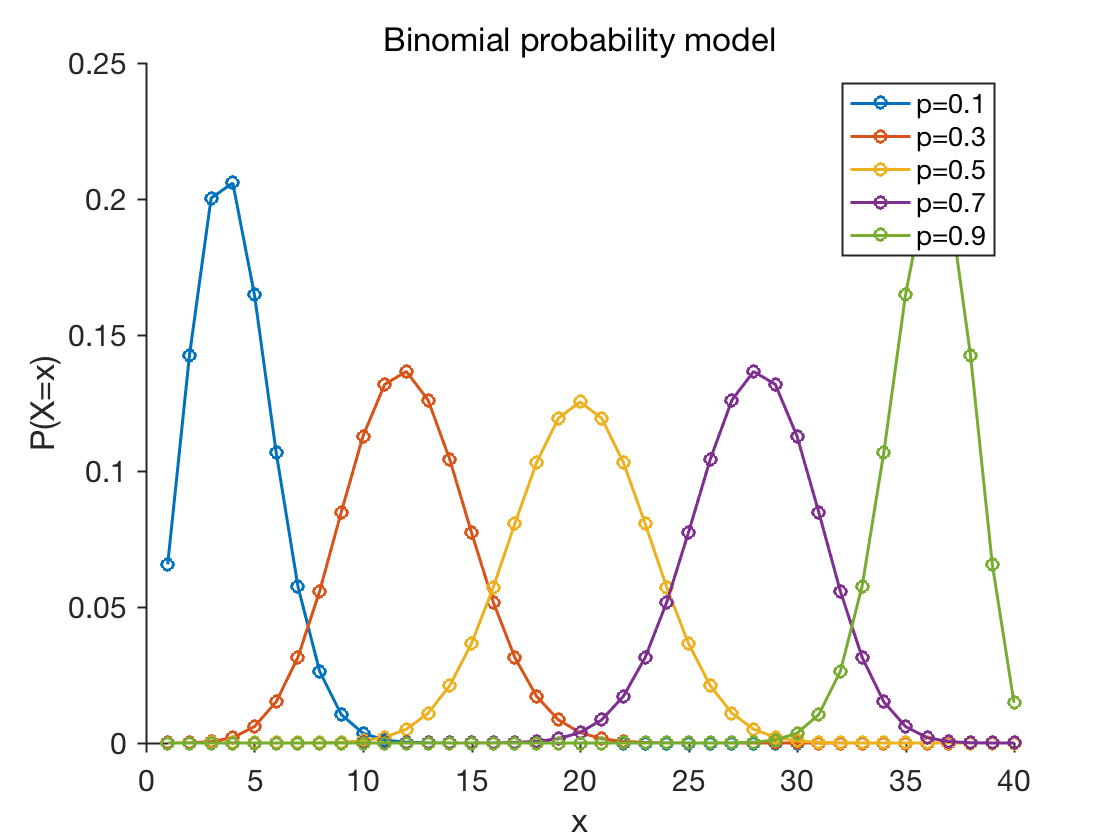

% multiple p 
p_all = 0.1:0.2:1;
n = 40;
x = 1:n;
legend_cell = cell(numel(p_all),1);
cprob = cell(numel(p_all),1);

close all;

figure; 
for i = 1:numel(p_all)
    p = p_all(i);
    q = 1-p;
    % Binomial probability X = x
    prob = factorial(n)./(factorial(x).*factorial(n-x)) .* (p.^x) .* (q.^(n-x));
    
    % Calculating cumulative probability, P(X <= x)
    cprob{i}(1) = 0;
    for j = 1:numel(prob)
        cprob{i}(j+1) = cprob{i}(j)+prob(j);
    end
    hold on;
    plot(prob, 'o-', 'linewidth', 1.5);
    legend_cell{i} = sprintf('p=%0.1f', p);
end

title('Binomial probability model')
xlabel('x')
ylabel('P(X=x)');

legend(legend_cell, 'location', 'eastoutside');

set(gca, 'linewidth', 1, 'fontsize', 15, 'tickdir', 'out');
set(gcf, 'color', 'w'); 
box off;

## Cumulative probability function

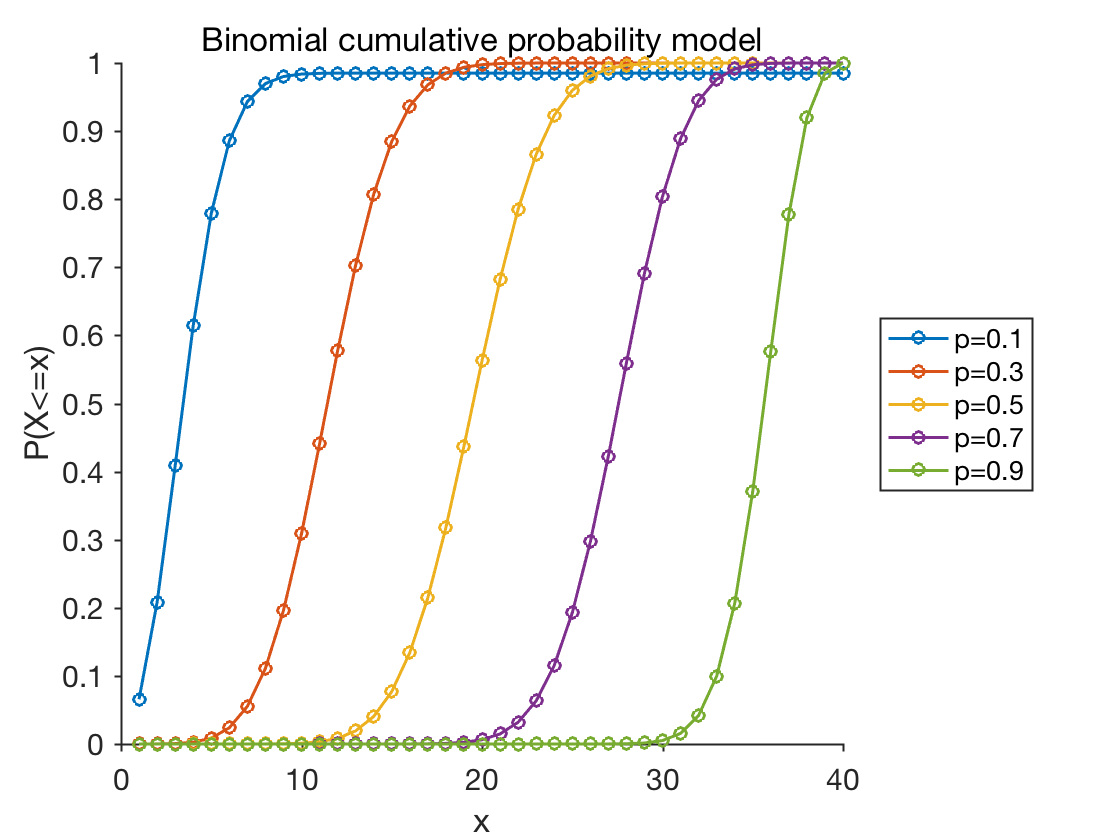


figure;
for i = 1:numel(p_all)
    p = p_all(i);
    hold on;
    % plot cumulative probability
    plot(cprob{i}(2:end), 'o-', 'linewidth', 1.5);
    legend_cell{i} = sprintf('p=%0.1f', p);
end

title('Binomial cumulative probability model')
xlabel('x')
ylabel('P(X<=x)');

legend(legend_cell, 'location', 'eastoutside');

set(gca, 'linewidth', 1, 'fontsize', 15, 'tickdir', 'out');
set(gcf, 'color', 'w'); 
box off;